# Part 4: ばね質点モデルで見る電力系統

電力系統で何が起きているのかを頭の中で思い描くのは、簡単ではありません。交流で送るので式には三角関数が必ず現れ（非線形）、試験用の系統でも母線や発電機は数十あり（ノードが多い）、そもそも電圧も電流も目に見えません。そのため、「負荷が増えると周波数はなぜ下がるのか」「電力系統の慣性とは何か」「過渡安定性が崩れるとき何が起きているのか」といった問いに、直感で答えるのは難しくなります。

この Part では、電気の系統を、思い描ける機械の系に置き換えます。各母線の電圧を平面の上の点、送電線をその間のばねと見るのです。この見方は以前からあり、野田モデルは 2 ノードの系統を機械のモデルで説明し、Gronquist らは多数の発電機を含む系統を、フェーザの平面上の質点とばねのアニメーションとして見せました。このライブスクリプトでは、まずばねの式を潮流計算の結果で数値として確かめ、そのあと GUILDA の `plot_spring_model` で、潮流、周波数の低下、脱調、電圧崩壊を、ばねと質点の動きとして見ていきます。

**この Part で分かること**

- 電圧を平面上の点（フェーザ）、送電線をばねと見る考え方と、その式（ばねの力 $F_{ij} = B_{ij}(V_j - V_i)$ と、その接線・半径方向への分解）

- 潮流計算の解が、すべてのばねがつり合う位置になる理由と、負荷が増えたときのばねの伸び

- 負荷の増加で絵全体が回る（周波数が下がる）ことと、慣性・ガバナの働き

- 同期電動機の消費が大きく増えると、ばねが伸び切って脱調すること

- 漏斗の形の曲面 $z = \log|V|$ の上で、電圧崩壊が質点の滑り落ちる動きとして見えること

知識ページ: [Part 4: 可視化機能：ばね質点モデル](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part4-spring-mass-model.html","-browser"))（ブラウザで開きます）。知識ページのグラフは、すべてこのライブスクリプトで描けます。

**注意**: GUILDA を起動してから（`>> GUILDA`）実行してください。上のリンクも、起動した GUILDA の場所からページを開きます。全体の実行には 1〜2 分かかります。

## 1. 電圧を平面上の点として置く

各母線の電圧は 50 Hz または 60 Hz の正弦波です。平常の運転では、すべての母線が同じ周波数で振動していて、違うのは振幅と波のずれ（位相）だけです。そこで、定格の周波数で回る座標から波を見ると、振動は消え、各母線の電圧は止まった矢印になります。これが**フェーザ**です。


$$v_i(t) = \sqrt{2}\,|V_i|\cos\bigl(2\pi f_0 t + \theta_i\bigr) \quad\longleftrightarrow\quad V_i = |V_i|\,e^{j\theta_i}$$


$v_i(t)$ は母線 $i$ の電圧の瞬時値、$|V_i|$ はその実効値、$\theta_i$ は位相、$f_0$ は定格の周波数です。矢印の長さが電圧の大きさ、角度が位相です。

同梱の IEEE 9 母線系統（発電機 3 台、負荷 3 つ）の潮流計算を解き、9 つの母線の電圧を平面に置いてみます。

net = network.IEEE9bus(LocalController=true);
[pf, flag] = net.calculate_powerflow();
flag

flag = 1

cv_V = pf.tab_bus.Vphasor;                             % 電圧フェーザ [pu]
sv_bus = string(pf.tab_bus.Properties.RowNames);
pf.tab_bus(:, ["V", "Varg", "Vphasor"])

ans = 9×3 table
               V         Varg            Vphasor     
            _______    _________    _________________

    B001       1.04            0       1.04+0i       
    B002      1.025      0.16197     1.0116+0.16529i 
    B003      1.025     0.081415     1.0216+0.083358i
    B004     1.0258     -0.03869      1.025-0.039678i
    B005    0.99563    -0.069618    0.99322-0.069258i
    B006     1.0127    -0.064357     1.0106-0.065127i
    B007     1.0258     0.064921     1.0236+0.066547i
    B008     1.0159     0.012698     1.0158+0.012899i
    B009     1.0324     0.034326     1.0317+0.035429i


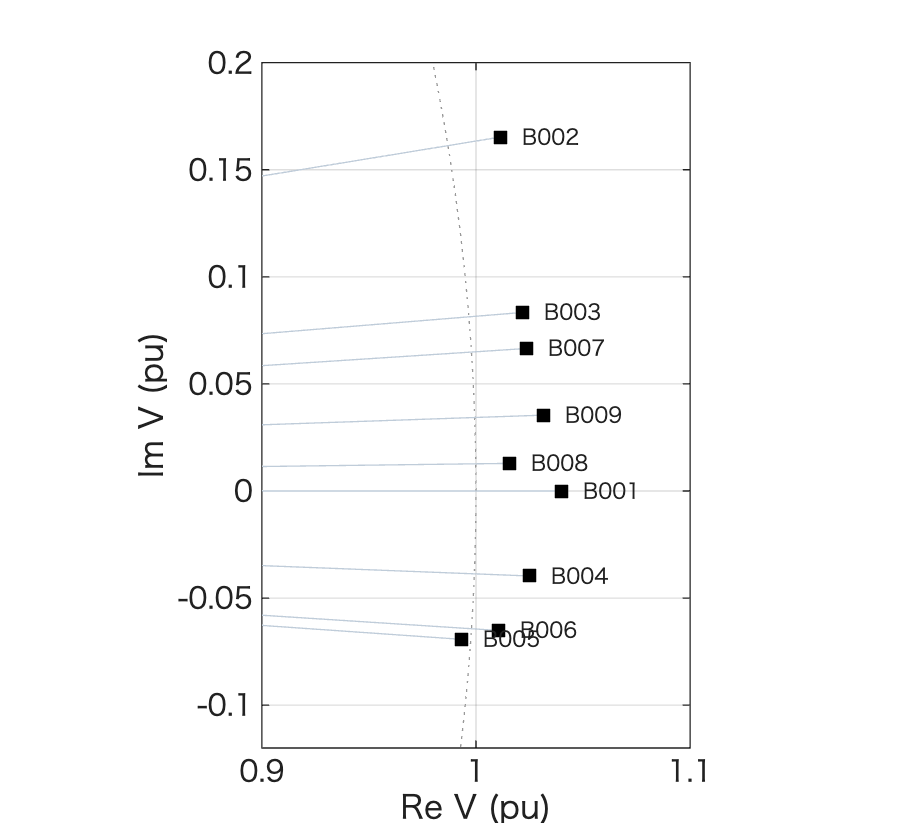


figure(Position=[100 100 460 420]);
ax = axes; hold(ax, "on");
rv_th = linspace(0, 2 * pi, 361);
plot(ax, cos(rv_th), sin(rv_th), ":", Color=[0.6 0.6 0.6]);    % |V| = 1 の円
plot(ax, [zeros(9, 1), real(cv_V)]', [zeros(9, 1), imag(cv_V)]', Color=[0.75 0.8 0.85]);
plot(ax, real(cv_V), imag(cv_V), "s", MarkerSize=6, MarkerFaceColor="k", Color="k");
text(ax, real(cv_V) + 0.01, imag(cv_V), sv_bus, FontSize=8);
axis(ax, "equal"); xlim(ax, [0.9, 1.1]); ylim(ax, [-0.12, 0.2]); grid(ax, "on"); box(ax, "on");
xlabel(ax, "Re V (pu)"); ylabel(ax, "Im V (pu)");

原点から見ると、9 つの点はすべて半径 1 前後の円の近くに、少しずつ違う角度で並んでいます（図は点のまわりを拡大しています）。発電機の母線（`B001`〜`B003`）は角度が進み、負荷の母線（`B005`、`B006`、`B008`）は遅れています。すべての母線の点を同じ平面に置くと、系統全体の状態が点の並びとして 1 枚の絵になります。

平常の運転では、点は止まっています。系統の周波数が定格より低くなると、どの波も回る座標より遅れていくので、すべての点がそろって時計回りに回り始めます。高くなると反時計回りです。周波数の変化は、絵全体の回転として見えます（4 節）。

## 2. 送電線をばねに見立てる

次に、点どうしをつなぎます。母線 $i$ から母線 $j$ への送電線に流れ込む電流は、2 つの電圧の差に比例します。送電線の抵抗と対地静電容量を無視して、リアクタンス $X_{ij}$ だけでできているとすると、アドミタンスは $y_{ij} = 1/(jX_{ij}) = -jB_{ij}$（$B_{ij} = 1/X_{ij}$）で、次の式になります。


$$I_{ij} = y_{ij}\,(V_i - V_j)$$



$$F_{ij} := -j\,I_{ij} = B_{ij}\,(V_j - V_i)$$


2 つ目の式はフックの法則（ばねの力 ＝ ばね係数 × 伸び、向きは相手の端へ）と同じ形です。「伸び」は 2 つの点の差 $V_j - V_i$、「ばね係数」は送電線のサセプタンス $B_{ij} = 1/X_{ij}$、「力」$F_{ij}$ は電流を −90° 回したもの（$-j$ を掛けたもの）です。短くて太い送電線（$X$ が小さい）ほど、硬いばねになります。

この力を、$V_i$ を通る円に沿う成分（接線方向）と、半径に沿う成分（半径方向）に分けます。母線 $i$ から送電線へ送り出す複素電力を $S_{ij} = V_i\,\overline{I_{ij}} = P_{ij} + jQ_{ij}$ とすると、$V_i$ の向きから見た力は次のようになります。


$$e^{-j\theta_i}\,F_{ij} = -\,\frac{Q_{ij} + j\,P_{ij}}{|V_i|}$$


実部が半径方向、虚部が接線方向の成分です。ばねは母線 $i$ を、円に沿って後ろへ $P_{ij}/|V_i|$ の力（中心のまわりのトルクはちょうど $P_{ij}$）で、中心へ向かって $Q_{ij}/|V_i|$（無効電流）の力で引きます。つまり、**有効電力は円に沿う向きのトルク、無効電流は中心に向かう向きの力**です。

### 潮流計算の結果で確かめる

この分解は $S_{ij} = V_i\overline{I_{ij}}$ の書き換えなので、抵抗や対地静電容量があっても成り立ちます。潮流計算の結果のブランチの表（`tab_branch`）には、両端の母線 `From`・`To`、送り端の電力 `Pfrom`、`Qfrom` と電流 `Ifrom` が入っています。母線の表（`tab_bus`）の電圧フェーザ `Vphasor` と合わせて、左辺（`Fcurrent`、電流から）と右辺（`Fpower`、電力から）を計算し、ブランチの表に列として足して比べます。

tab_br = pf.tab_branch(:, ["From", "To", "Pfrom", "Qfrom", "Ifrom"]);
cv_Vfrom = pf.tab_bus{tab_br.From, "Vphasor"};                                   % 送り端の電圧
cv_Vto = pf.tab_bus{tab_br.To, "Vphasor"};                                       % 受け端の電圧
tab_br.Fcurrent = exp(-1j * angle(cv_Vfrom)) .* (-1j * tab_br.Ifrom);           % e^{-jθi} F_ij
tab_br.Fpower = -(tab_br.Qfrom + 1j * tab_br.Pfrom) ./ abs(cv_Vfrom);           % -(Q + jP)/|Vi|
tab_br(:, ["From", "To", "Fcurrent", "Fpower"])

ans = 9×4 table
              From       To           Fcurrent               Fpower      
             ______    ______    __________________    __________________

    ET001    "B001"    "B004"     -0.26006-0.68886i     -0.26006-0.68886i
    ET002    "B002"    "B007"    -0.064914-1.5902i     -0.064914-1.5902i 
    ET003    "B003"    "B009"      0.10595-0.82927i      0.10595-0.82927i
    EL004    "B004"    "B005"     -0.22318-0.39908i     -0.22318-0.39908i
    EL005    "B004"    "B006"    -0.010041-0.29932i    -0.010041-0.29932i
    EL006    "B005"    "B007"      0.11362+0.8469i       0.11362+0.8469i 
    EL007    "B006"    "B009"      0.13288+0.5872i       0.13288+0.5872i 
    EL008    "B007"    "B008"     0.007773-0.74461i     0.007773-0.74461i
    EL009    "B008"    "B009"      0.23916+0.23719i      0.23916+0.23719i


2 つの列は一致します。たとえば `EL008`（母線 7 → 8）は虚部（接線方向）が約 −0.74 です。母線 7 から 8 へ 0.76 pu の有効電力を送っていることが、母線 7 を後ろへ引く力 $P/|V| = 0.764/1.026$ として現れています。

### 有効電力は角度の差で決まる

半径 $|V_i|$ と $|V_j|$ の円の上にあり、角度の差が $\delta = \theta_i - \theta_j$ の 2 つの点では、上の式の虚部から、ばねのトルクは次のようになります。


$$P_{ij} = B_{ij}\,|V_i|\,|V_j|\,\sin\delta$$


損失のない送電線で送る有効電力の、おなじみの式です。アドミタンス行列の非対角要素 $Y_{ij} = -y_{ij}$ からばね係数 $B_{ij} = \mathrm{Im}\,Y_{ij}$ を取り出し、この式の値を潮流計算の `Pfrom` と比べます。

[~, iv_from] = ismember(tab_br.From, sv_bus);      % Y の行と列の番号（tab_bus の順）
[~, iv_to] = ismember(tab_br.To, sv_bus);
tab_br.B = imag(pf.cm_Y(sub2ind(size(pf.cm_Y), iv_from, iv_to)));               % ばね係数 B_ij [pu]
tab_br.delta = angle(cv_Vfrom) - angle(cv_Vto);                                  % 角度の差 [rad]
tab_br.Pspring = tab_br.B .* abs(cv_Vfrom) .* abs(cv_Vto) .* sin(tab_br.delta);  % B|Vi||Vj|sinδ
tab_br(:, ["From", "To", "B", "delta", "Pspring", "Pfrom"])

ans = 9×6 table
              From       To        B         delta      Pspring      Pfrom  
             ______    ______    ______    _________    ________    ________

    ET001    "B001"    "B004"    17.361      0.03869     0.71641     0.71641
    ET002    "B002"    "B007"        16     0.097046        1.63        1.63
    ET003    "B003"    "B009"    17.065      0.04709        0.85        0.85
    EL004    "B004"    "B005"    11.604     0.030928     0.36647     0.40937
    EL005    "B004"    "B006"    10.511     0.025667     0.28021     0.30704
    EL006    "B005"    "B007"    5.9751     -0.13454    -0.81853     -0.8432
    EL007    "B006"    "B009"    5.5882    -0.098683    -0.57557    -0.59463
    EL008    "B007"    "B008"    13.698     0.052223      0.7451      0.7638
    EL009    "B008"    "B009"    9.7843    -0.021628    -0.22191    -0.24095


変圧器（`ET001`〜`ET003`、抵抗なし）では 2 つの値は一致し、送電線（`EL004`〜`EL009`）でも 1 割ほどの差に収まります。差は送電線の抵抗によるものです（$\sin\delta$ の式は抵抗を無視しています）。どのブランチでも、電力は角度が進んだ点から遅れた点へ流れ、角度の差が大きいほど、ばねが伝える電力は大きくなります。ただし 5 節で見るように、それには限界があります。

## 3. 潮流計算はばねのつり合い

母線につながる機器は、その点を押したり引いたりします。発電機は系統へ電力を送り出すので、点を円に沿って前（反時計回り）へトルク $P$ で押します。負荷は電力を取り出すので、点を後ろへ引きます。ばねは、どの点でも、その押す力・引く力を打ち消すところまで伸びます。母線 $i$ の機器が注入する電力を $S_i = P_i + jQ_i$ とすると、母線での力のつり合いは次の式です。


$$f_i + \sum_{j} F_{ij} = 0, \qquad f_i = e^{j\theta_i}\,\frac{Q_i + j\,P_i}{|V_i|}$$


2 節の分解から、これは母線の電力方程式 $S_i = \sum_j S_{ij}$ と同じです。つまり、**潮流計算は、すべてのばねがつり合う位置を求める計算**で、そのときの点の角度と半径が、潮流計算の解の電圧フェーザです。

ばねだけでは決まらないことが 1 つあります。絵全体を同じ角度だけ回しても、どのばねの長さも変わらず、力のつり合いもそのままです。この回転対称性があるので、潮流計算では角度を固定する（ふつうは 0 にする）slack 母線が必要になります。slack 母線は絵の基準の向きを決めるだけで、物理的には何も変えません。

GUILDA は、系統全体についてこの絵を `plot_spring_model` で描きます。`initialize` で平衡点を求めてから、`net.plot_spring_model` で描きます（知識ページの図。点の付近を拡大し、母線の名前を省いています）。

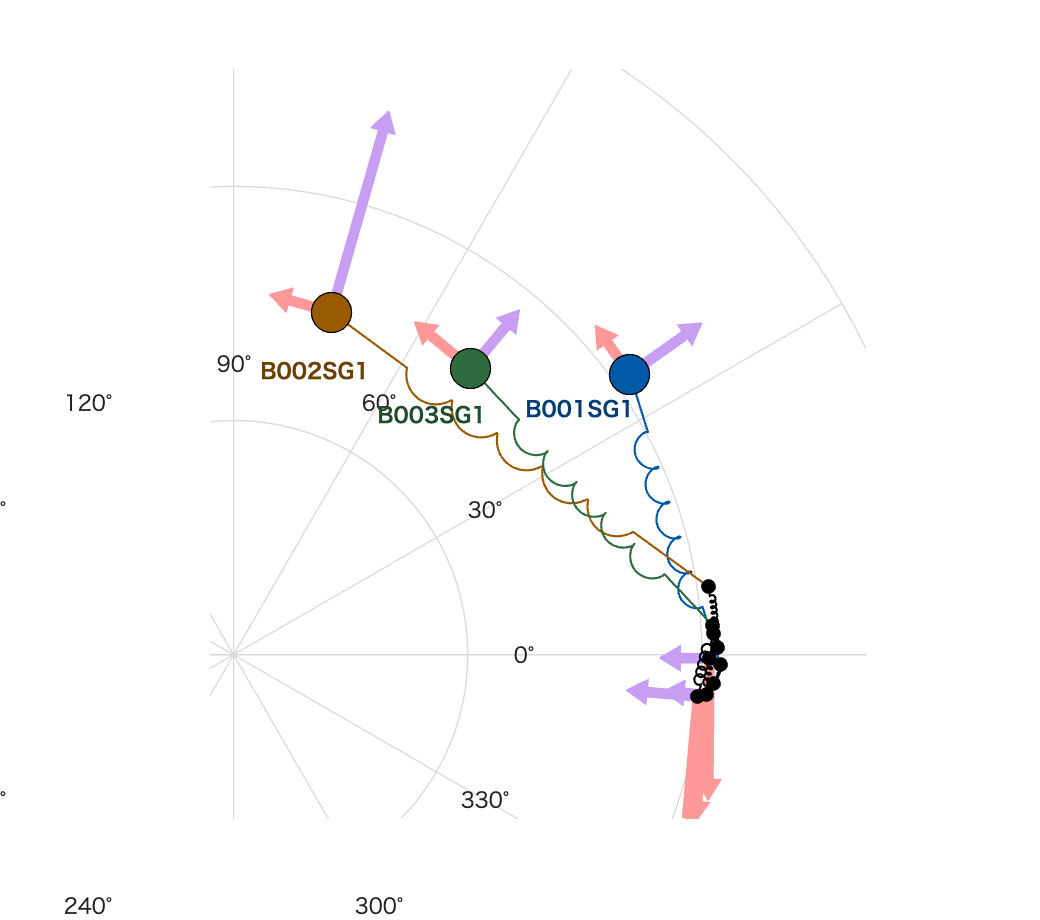

[~, flag] = net.initialize();
c_blue = [0 89 167] / 255;      % 図の色（知識ページの図と同じ）
c_orange = [154 91 0] / 255;
c_green = [46 107 63] / 255;
figure(Position=[100 100 520 460]);
ax = axes;
G = net.plot_spring_model(Parent=ax);
G.ShowValue = false;
G.ShowLegend = false;
G.NodeLabel(G.sct_data.sv_kind == "bus") = "";
G.set_style("B001SG1", Color=c_blue);
G.set_style("B002SG1", Color=c_orange);
G.set_style("B003SG1", Color=c_green);
set(ax, XLim=[-0.05, 1.35], YLim=[-0.35, 1.25]);
set(findall(ax, "Type", "text"), FontSize=8);

黒い四角が 9 つの母線、大きな丸が 3 台の発電機（`B001SG1` が青、`B002SG1` が橙、`B003SG1` が緑）の内部電圧で、発電機のリアクタンスのばねで母線とつながっています。桃色の矢印が有効電力 $P$、紫の矢印が無効電流 $I_q$ です。発電機の点は母線より前（反時計回りの向き）にあり、母線を前へ押しています。

**注意**: 図は母線の位相角の平均が 0 になる向きで描くので、全体の向きは 1 節の図（`B001` が 0）と少しずれます。比べるのは点どうしの位置の差です。

### 負荷を増やすと、ばねが伸びる

3 つの負荷を 1.5 倍にして潮流計算を解き、もとの負荷の場合と並べて描きます。負荷の引く力が強くなると、ばねはどれだけ伸びるでしょうか。もとの `net` は後の節で使うので、負荷を増やす系統は別に読み込みます。

netHeavy = network.IEEE9bus(LocalController=true);
tab_load = netHeavy.get_parameter("powerflow", Key="load-impedance")   % 3 つの負荷の P、Q

tab_load = 3×2 table
                  P        Q  
                _____    _____

    B005LRX1    -1.25     -0.5
    B006LRX1     -0.9     -0.3
    B008LRX1       -1    -0.35


tab_load.P = 1.5 * tab_load.P;
tab_load.Q = 1.5 * tab_load.Q;
netHeavy.set_parameter("powerflow", tab_load);
[pfHeavy, flag] = netHeavy.calculate_powerflow();
flag

flag = 1

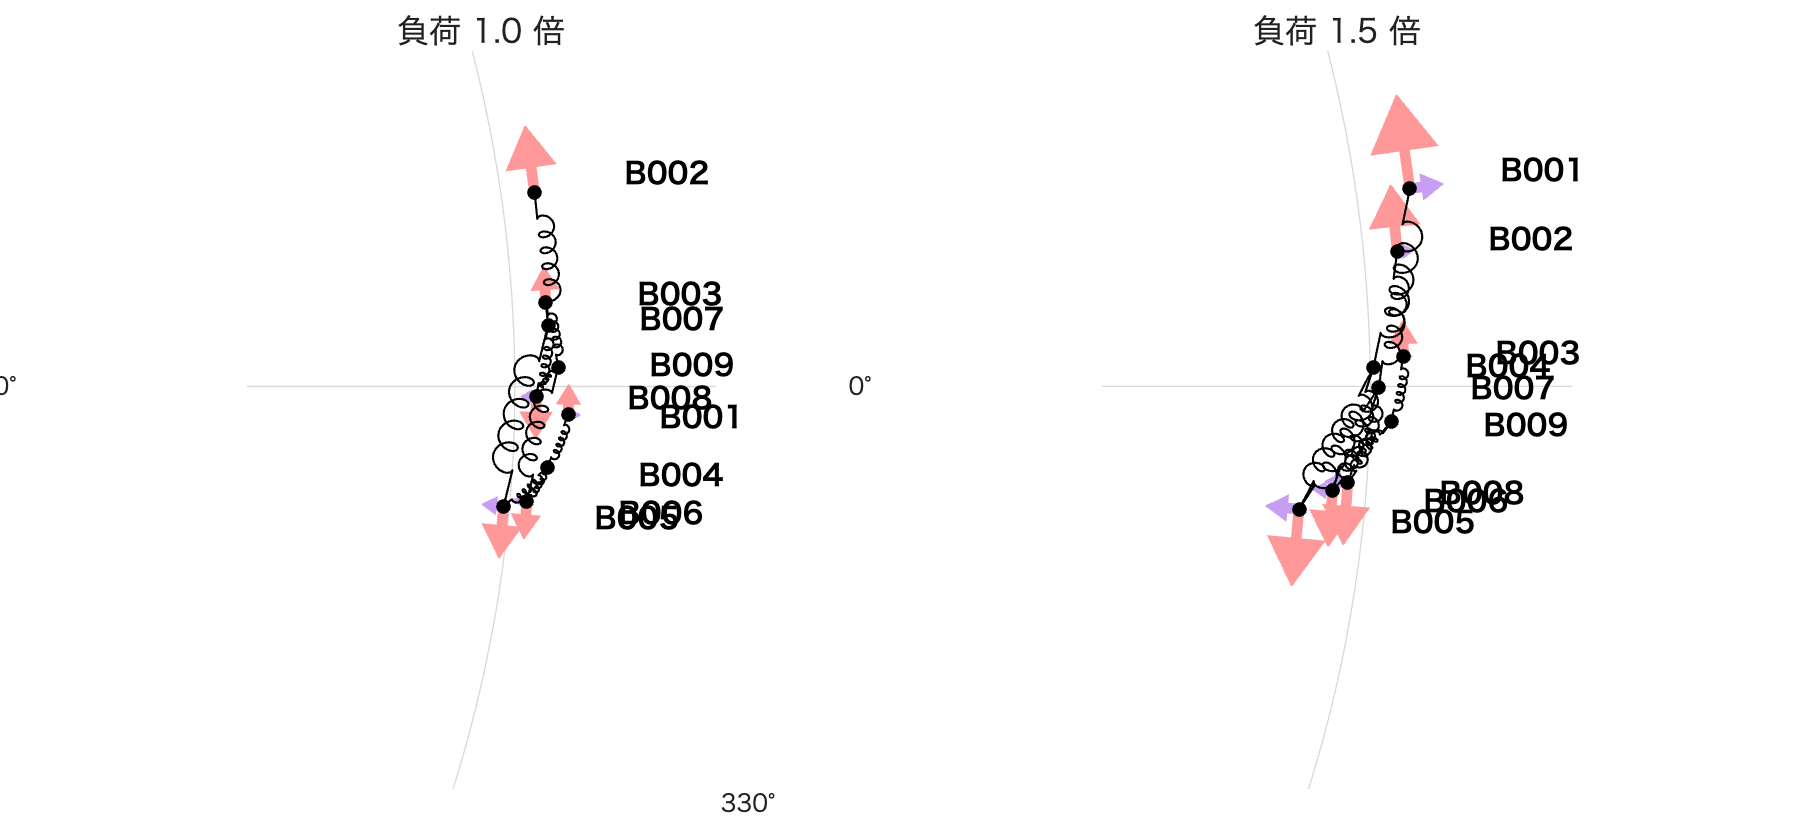

figure(Position=[100 100 900 420]);
layout = tiledlayout(1, 2, TileSpacing="compact", Padding="compact");
c_pf = {pf, pfHeavy};
sv_title = ["負荷 1.0 倍", "負荷 1.5 倍"];
for i = 1:2
    G = c_pf{i}.plot_spring_model(Parent=nexttile(layout));
    G.ShowValue = false;
    G.ShowLegend = false;
    G.ArrowScaleP = 0.03;
    G.ArrowScaleQ = 0.03;
    axis(G.ax, [0.8 1.15 -0.3 0.25])
    title(G.ax, sv_title(i))
end

tab_angle = pf.tab_bus(:, ["Varg", "V"]);              % 1.0 倍の位相 [rad] と大きさ [pu]
tab_angle.VargHeavy = pfHeavy.tab_bus.Varg;             % 1.5 倍
tab_angle.VHeavy = pfHeavy.tab_bus.V;
tab_angle

tab_angle = 9×4 table
              Varg          V       VargHeavy    VHeavy 
            _________    _______    _________    _______

    B001            0       1.04            0       1.04
    B002      0.16197      1.025    -0.044152      1.025
    B003     0.081415      1.025      -0.1202      1.025
    B004     -0.03869     1.0258     -0.12824     1.0024
    B005    -0.069618    0.99563     -0.23831    0.95138
    B006    -0.064357     1.0127      -0.2218    0.97508
    B007     0.064921     1.0258     -0.14308     1.0063
    B008     0.012698     1.0159     -0.21508    0.98589
    B009     0.034326     1.0324     -0.16805      1.016


1.5 倍では、slack 母線（`B001`）と負荷の母線（`B005`、`B006`、`B008`）の間が大きく開き、点の並びが長くなっています。増えた負荷は slack 母線の発電機が引き受けるので、`B001` から負荷の母線へ向かうばねが伸び、角度の差が開きます。表では、`B005` の位相が −0.070 rad（−4.0°）から −0.238 rad（−13.7°）へ遅れ、`B001` との角度の差が 3 倍以上に開いています。$P = B|V_i||V_j|\sin\delta$ から、同じばねでより多くの電力を送るには角度の差を広げるしかない、ということが絵に表れています。負荷の母線の点は円の内側へも少し下がり（電圧の低下）、これは負荷の無効電力が点を中心へ引く力が強まったためです。

**注意**: 潮流計算の結果は発電機の状態を持たないので、`ResultPF` の `plot_spring_model` は母線だけを描きます。発電機の点まで描くには、`net.plot_spring_model` を使います。

## 4. 周波数が下がる理由と慣性

ここまでは、発電機を単に押す力として扱ってきました。動きを見るために、発電機にも自分の点を持たせます。リアクタンスの奥にある内部電圧の点です。この点は発電機の回転子に当たるので、質量（慣性 $M$）を持ちます。タービンが機械入力でこの点を前へ押し、母線へのばねが送り出す電気出力の分だけ後ろへ引きます。母線の点には質量がなく、いつでもすぐにつり合いの位置へ移ります。点の運動は、まさに動揺方程式 $M\dot{\omega} = P_\mathrm{m} - P_\mathrm{e} - D\omega$ です。

負荷が増えたときに何が起きるかを、GUILDA で見てみます。同梱の系統 `network.Tutorial6bus` は、6 つの母線と、母線 1〜4 につながる古典モデルの同期機 G1〜G4（`B001SG1`〜`B004SG1`）でできています（リアクタンスの奥の内部電圧の大きさ |E| が一定。慣性 M = 10, 8, 6, 6、制動 D = 5）。G1 と G2 は発電機です。G3 と G4 は出力が負で、機械の負荷を回す同期電動機として運転しています。t = 1 s に、G3 と G4 の消費をそれぞれ 0.1 pu 増やします（機械入力 `Pmech` を 0.1 pu 下げます。add_input の値は平衡点の入力に足されます）。まだガバナはありません。

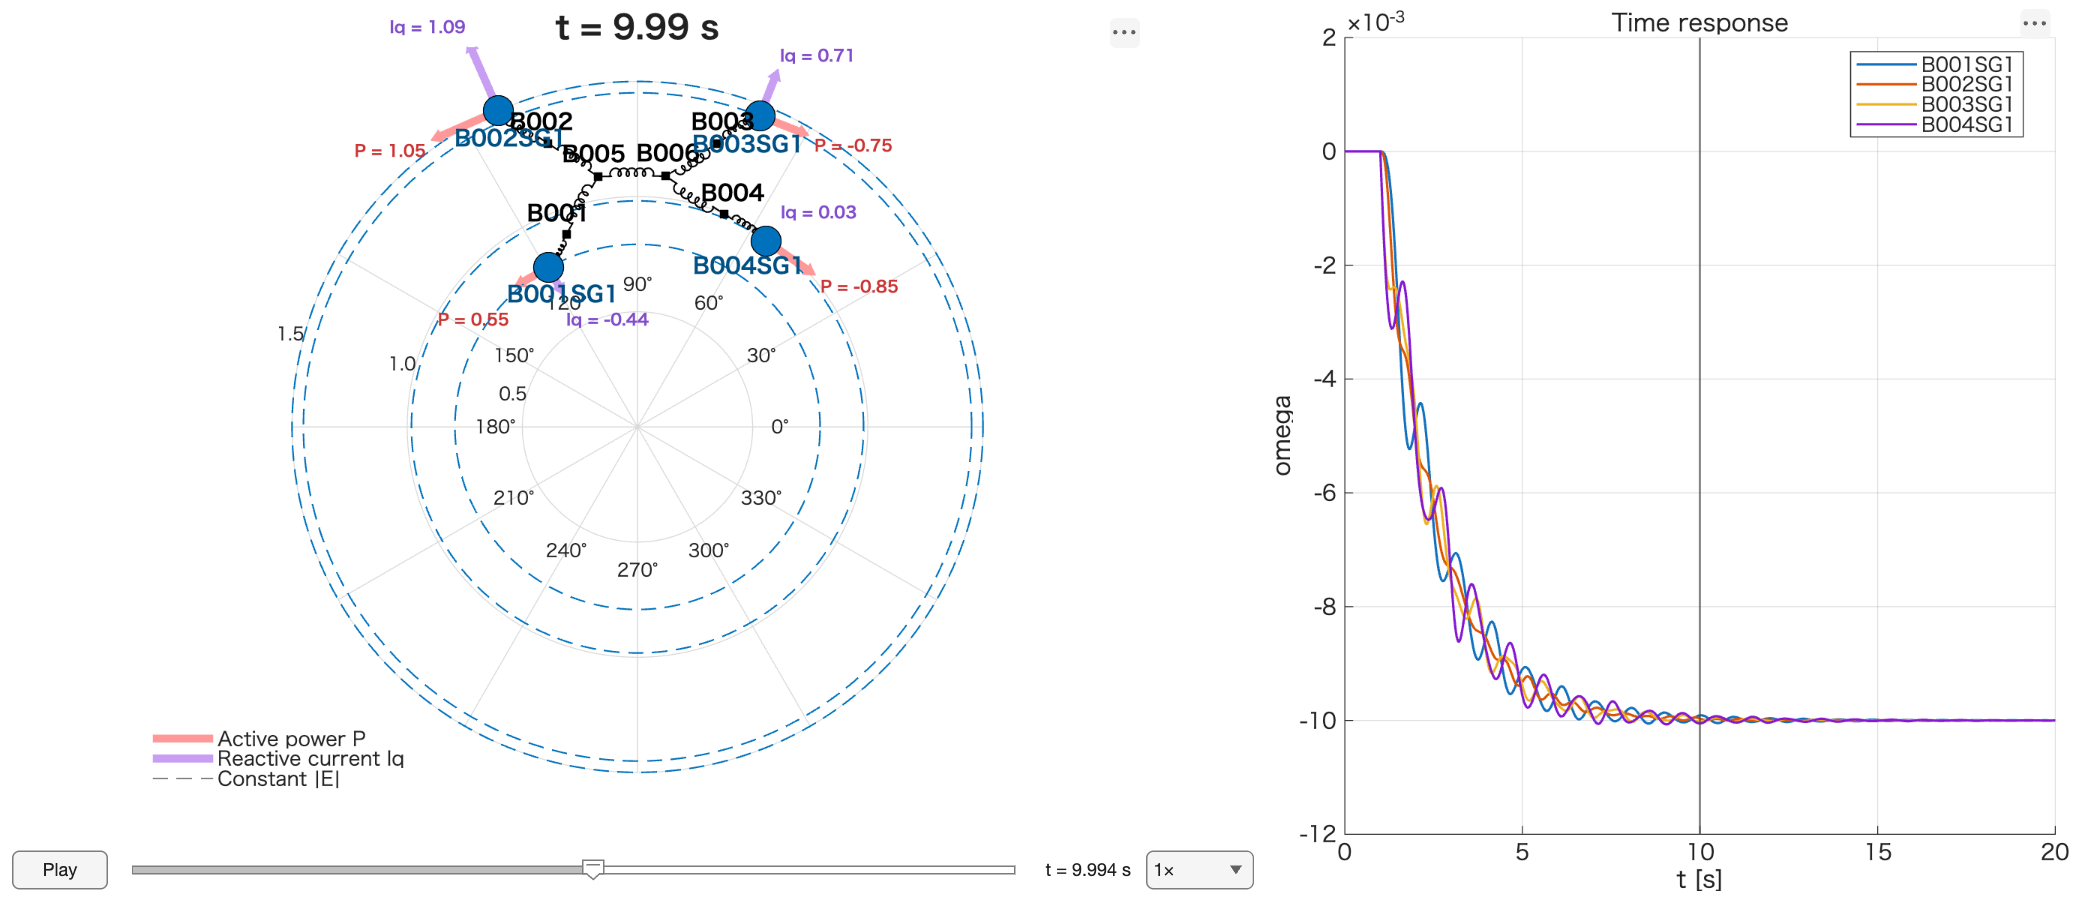

net = network.Tutorial6bus();
sc = net.add_scenario("step", Time=[0, 20]);
sc.add_input("B003SG1", "Pmech", -0.1, [1, 20]);
sc.add_input("B004SG1", "Pmech", -0.1, [1, 20]);
result = net.simulate("step", Progress="none");
[G, G_chart] = result.plot_spring_model();
G.set_time(10);

`[G, G_chart] = result.plot_spring_model()` は、1 つの図に左右に並べて描きます。左の `G` がばね質点の絵で、題名に時刻を示します。大きな丸が G1〜G4 の内部電圧、小さな四角が母線、桃色の矢印が有効電力 P、紫の矢印が無効電流 $I_q$、破線の円が一定に保たれる内部電圧の大きさです。右の `G_chart` は横のグラフで、4 台の回転速度のずれ omega [pu] を示し、縦線が表示中の時刻（ここでは `G.set_time(10)` で選んだ t = 10 s）を示します。50 Hz の系統では omega = −0.01 pu が −0.5 Hz です。

t = 1 s に G3 と G4 の機械入力が 0.1 pu 下がると、その引く力が G1 と G2 の押す力に勝ち、絵全体が時計回りに回り始めます。周波数の低下です。重い同期機の点は滑らかに動き出し、母線の点はすぐに後を追います。ガバナがないので、G1 と G2 の機械入力は変わりません。回転は、4 台の制動が増えた 0.2 pu を受け持つ速さ −0.2 / (4 × 5) = −0.01 pu、つまり −0.5 Hz に落ち着き、元には戻りません。最後の時刻の omega で確かめます。

tab_omega = result.get_trajectory("omega");
tab_omega(end, :)

ans = 1×5 table
    t     B001SG1    B002SG1     B003SG1       B004SG1  
    __    _______    _______    __________    __________

    20     -0.01      -0.01     -0.0099995    -0.0099998


4 台とも −0.01 pu です。これで、最初の問いのうち 2 つに機械の言葉で答えられます。

- **周波数はなぜ下がる？** 負荷が増えると、その引く力がタービンの押す力より強くなります。余った引く力はばねを通してすべての点に伝わり、絵全体がそろって後ろへ回り始めます。

- **慣性とは？** 発電機の点が持つ質量のことです。重い点は急には動き出せないので、回転は滑らかに始まり、周波数は最初ゆっくり下がります。

### ガバナと AGC を付ける

回転はひとりでには止まりません。制御がなければ、絵は制動で決まる一定の速さで回り続けます。ガバナは周波数のずれを検出して機械入力を増やすので、押す力が強まり、回転がゆっくりになります。垂下特性のガバナだけでは少しのずれが残ります。ずれの積分（AGC の役目）を加えると、周波数は定格の値へ戻ります。G1 と G2 に、ガバナ `gov-LPT3`（ここでは垂下率 5 %、時定数 3 s の遅れ）と積分の `agc-PI` を付けます。

net = network.Tutorial6bus();
sct_gov = struct(Prate=1, PLM=1000, droop=5, Tg=0, Ts=3, rate_max=Inf, rate_min=-Inf, pos_max=Inf, pos_min=-Inf);
for i = 1:2
    gen = net.a_Bus{i}.a_Component{1};
    gen.set_governor("gov-LPT3", parameter=sct_gov);
    net.add_global_controller("agc-PI", {gen}, parameter=struct(kP=0, kI=4));
end

INFO: The global controller 'PowerNetworkAGC1' is connected: Pmech_B001SG1_PowerNetworkAGC1 -> Pmech_B001SG1.
INFO: The global controller 'PowerNetworkAGC2' is connected: Pmech_B002SG1_PowerNetworkAGC2 -> Pmech_B002SG1.


net.initialize();

シナリオと描き方は上と同じです。t = 20 s を表示します。

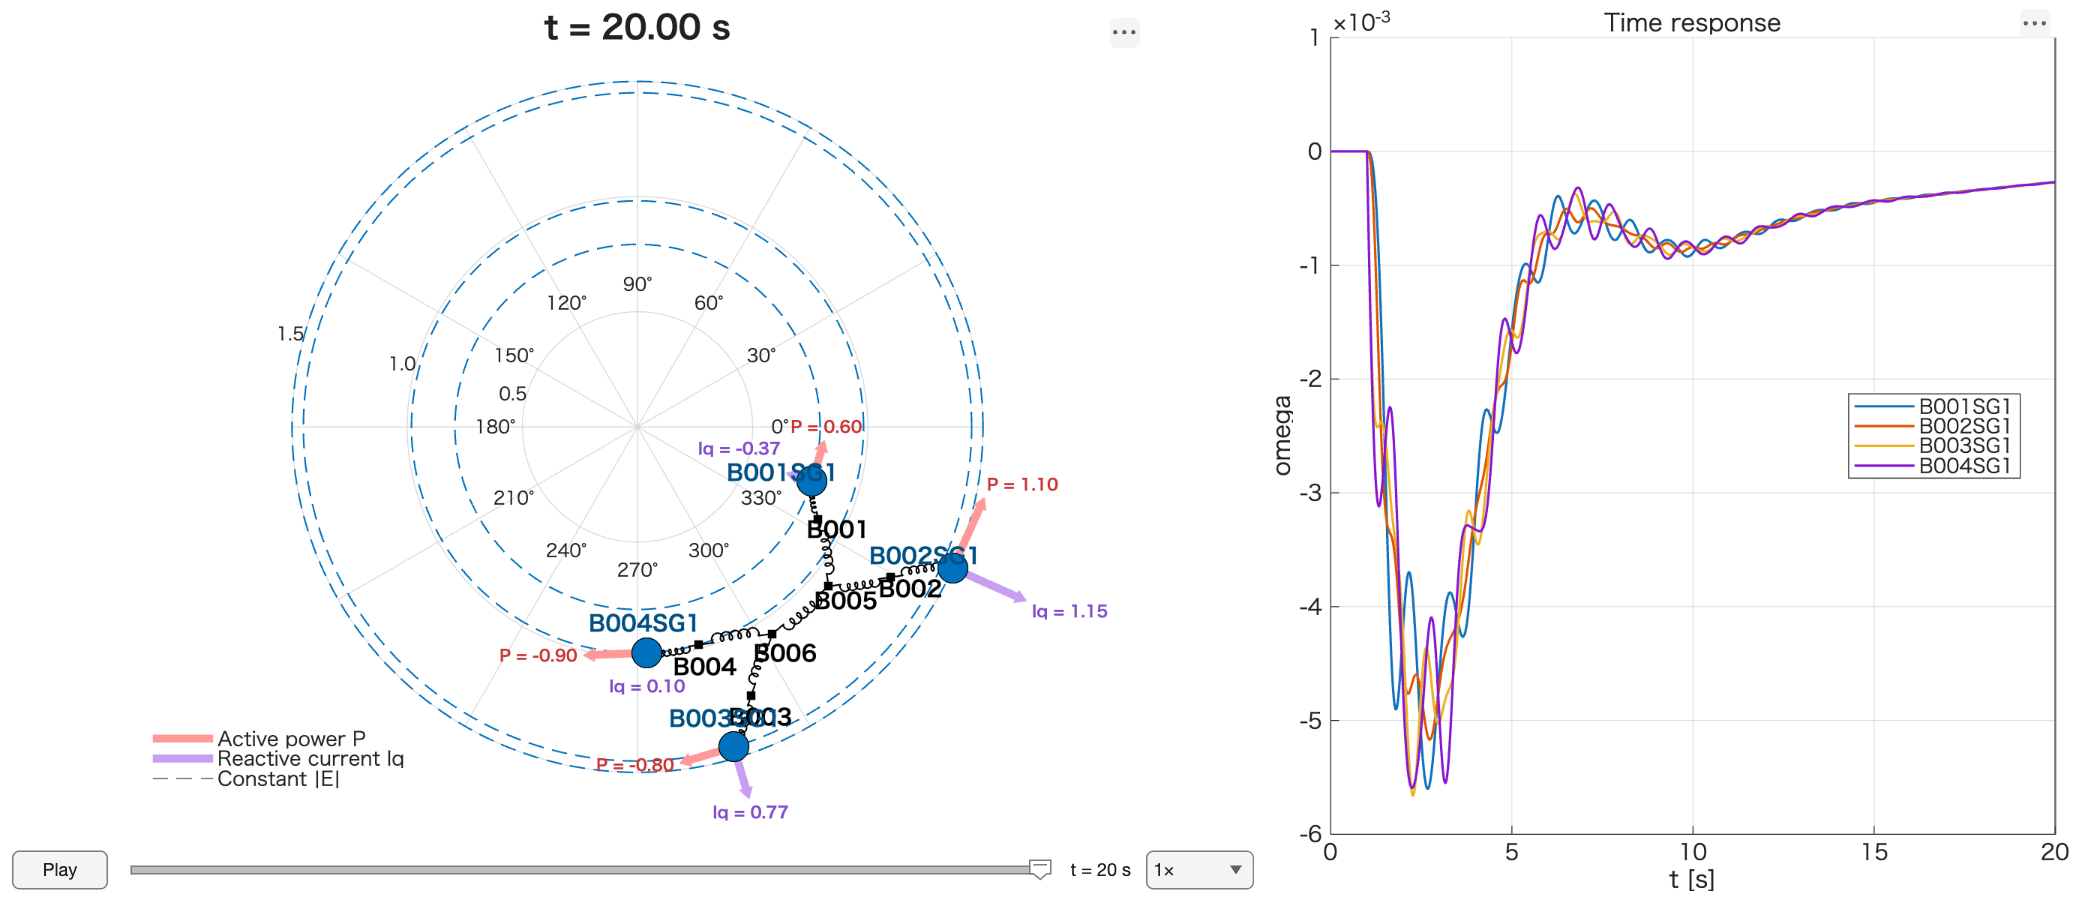

sc = net.add_scenario("step", Time=[0, 20]);
sc.add_input("B003SG1", "Pmech", -0.1, [1, 20]);
sc.add_input("B004SG1", "Pmech", -0.1, [1, 20]);
result = net.simulate("step", Progress="none");
[G, G_chart] = result.plot_spring_model();
G.set_time(20);

t = 1 s の後、絵は前と同じように時計回りに回り始め、omega は t ≈ 2.2〜2.7 s に約 −0.0055 pu（約 −0.28 Hz）まで下がります。その間にガバナが G1 と G2 の機械入力を上げます。その押す力が電動機の引く力に追いつくと回転は止まり、積分が omega を 0 へ戻していきます（20 s で約 −0.0003 pu、−0.01 Hz）。そのあと点は新しい位置で止まります。G1 と G2 はより強く押し、母線へ注入する P は 0.5 と 1.0 から約 0.6 と 1.1 pu になります。

tab_P = result.get_trajectory("P");
tab_P([1, end], ["t", "B001", "B002", "B003", "B004"])

ans = 2×5 table
    t      B001       B002       B003        B004  
    __    _______    ______    ________    ________

     0        0.5         1        -0.7        -0.8
    20    0.59853    1.0991    -0.79885    -0.89882


## 5. 脱調：ばねが伸び切る

このモデルのばねには特徴があります。ばねの端が円の上を動くことです。角度 $\delta$ だけ前へずれた点に、ばねが与えるトルクを考えます。はじめは、点が離れるほどトルクは大きくなります。ところが 90° を超えると、ばねは円に沿う向きより中心の向きを向くようになり、ばねは長くなっているのに、点を引き戻すトルクは小さくなっていきます。これが 2 節の式 $P_{ij} = B_{ij}|V_i||V_j|\sin\delta$ の $\sin\delta$ です。ばねの長さ $|V_i - V_j|$ とトルクを、$\delta$ に対して描いて比べます（$|V_i| = |V_j| = 1$、$B_{ij} = 1$）。

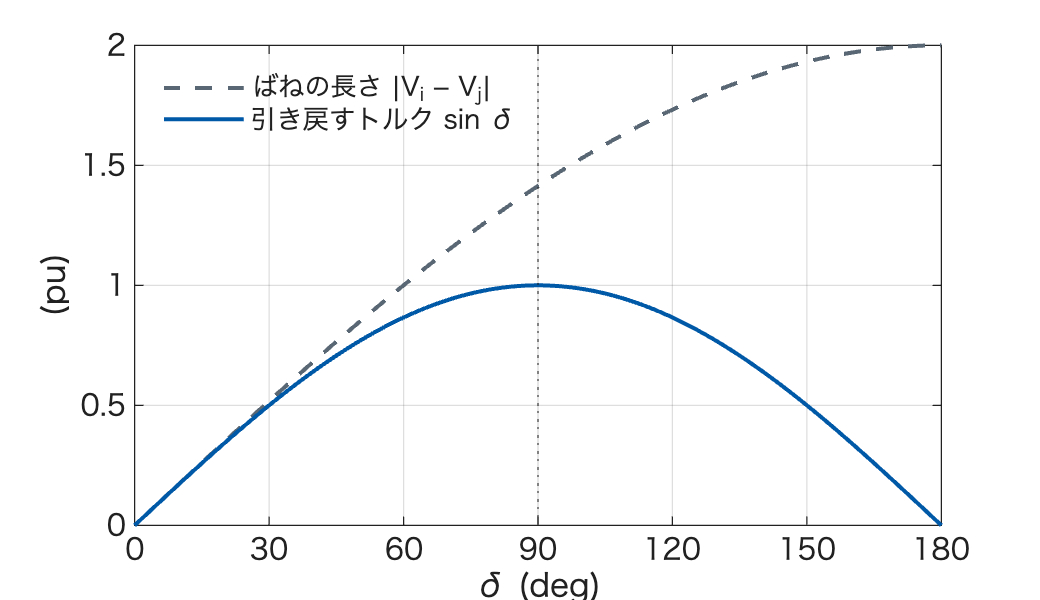

rv_d = linspace(0, 180, 181);
figure(Position=[100 100 520 300]);
ax = axes; hold(ax, "on");
plot(ax, rv_d, abs(1 - exp(1j * deg2rad(rv_d))), "--", Color=[0.35 0.4 0.45], LineWidth=1.5, DisplayName="ばねの長さ |V_i − V_j|");
plot(ax, rv_d, sind(rv_d), Color=c_blue, LineWidth=1.5, DisplayName="引き戻すトルク sin δ");
xline(ax, 90, ":", HandleVisibility="off");
set(ax, XLim=[0, 180], XTick=0:30:180, XGrid="on", YGrid="on", Box="on");
xlabel(ax, "δ (deg)"); ylabel(ax, "(pu)"); legend(ax, Location="northwest", Box="off");

ばねの長さは 180° まで増え続けますが、引き戻すトルクは 90° で最大になり、そのあとは減っていきます。これで 3 つ目の問いに答えられます。G3 と G4 が急に大きく消費を増やすと、その点はほかの点より後ろへ遅れ、系統のほかの部分へのばねが前へ引っ張ります。ばねがまだ十分に引けるうちは、4 節のように、点は揺れながら新しい角度に落ち着きます。増えた消費が大きすぎると、点は離れすぎて、ばねはもう引き連れられません。点は円を回って滑り、ほかの点と歩調をそろえられなくなります。脱調とは、ばねが支えきれないところまで伸び切ることです。

4 節の `network.Tutorial6bus` で、t = 1 s に G3 と G4 の消費をそれぞれ 0.3 pu 増やします。G1 と G2 には積分なしのガバナ（4 節の `sct_gov`）を付け、G3 と G4 の制動 D は 0 にします。脱調しても計算を続けるように `StopOnOutOfStep=false` とし、まず 10 秒まで計算して、2 台の電動機が止まる（omega が −1 pu になる）時刻を求めます。

net = network.Tutorial6bus();
for i = 1:2
    net.a_Bus{i}.a_Component{1}.set_governor("gov-LPT3", parameter=sct_gov);
end
for i = 3:4
    net.a_Bus{i}.a_Component{1}.tab_parameter.dynamics.D = 0;   % 電動機の制動なし
end
net.initialize();
sc = net.add_scenario("step", Time=[0, 20]);
sc.add_input("B003SG1", "Pmech", -0.3, [1, 20]);
sc.add_input("B004SG1", "Pmech", -0.3, [1, 20]);
result = net.simulate("step", Time=[0, 10], Progress="none", StopOnOutOfStep=false, MaxStep=0.005);
tab_omega = result.get_trajectory("omega");
sv_motor = ["B003SG1", "B004SG1"];
rv_tStop = zeros(1, 2);
for i = 1:2
    k = find(tab_omega.(sv_motor(i)) <= -1, 1);
    rv_tStop(i) = interp1(tab_omega.(sv_motor(i))(k-1:k), tab_omega.t(k-1:k), -1);
end
rv_tStop

rv_tStop =     7.5878    7.6456


2 台は約 7.6 s に止まります。止まった電動機を、その時刻にシナリオの `add_trip` で系統から切り離し、8 秒まで計算し直して描きます。t = 7.9 s（切り離しの後）を表示します。

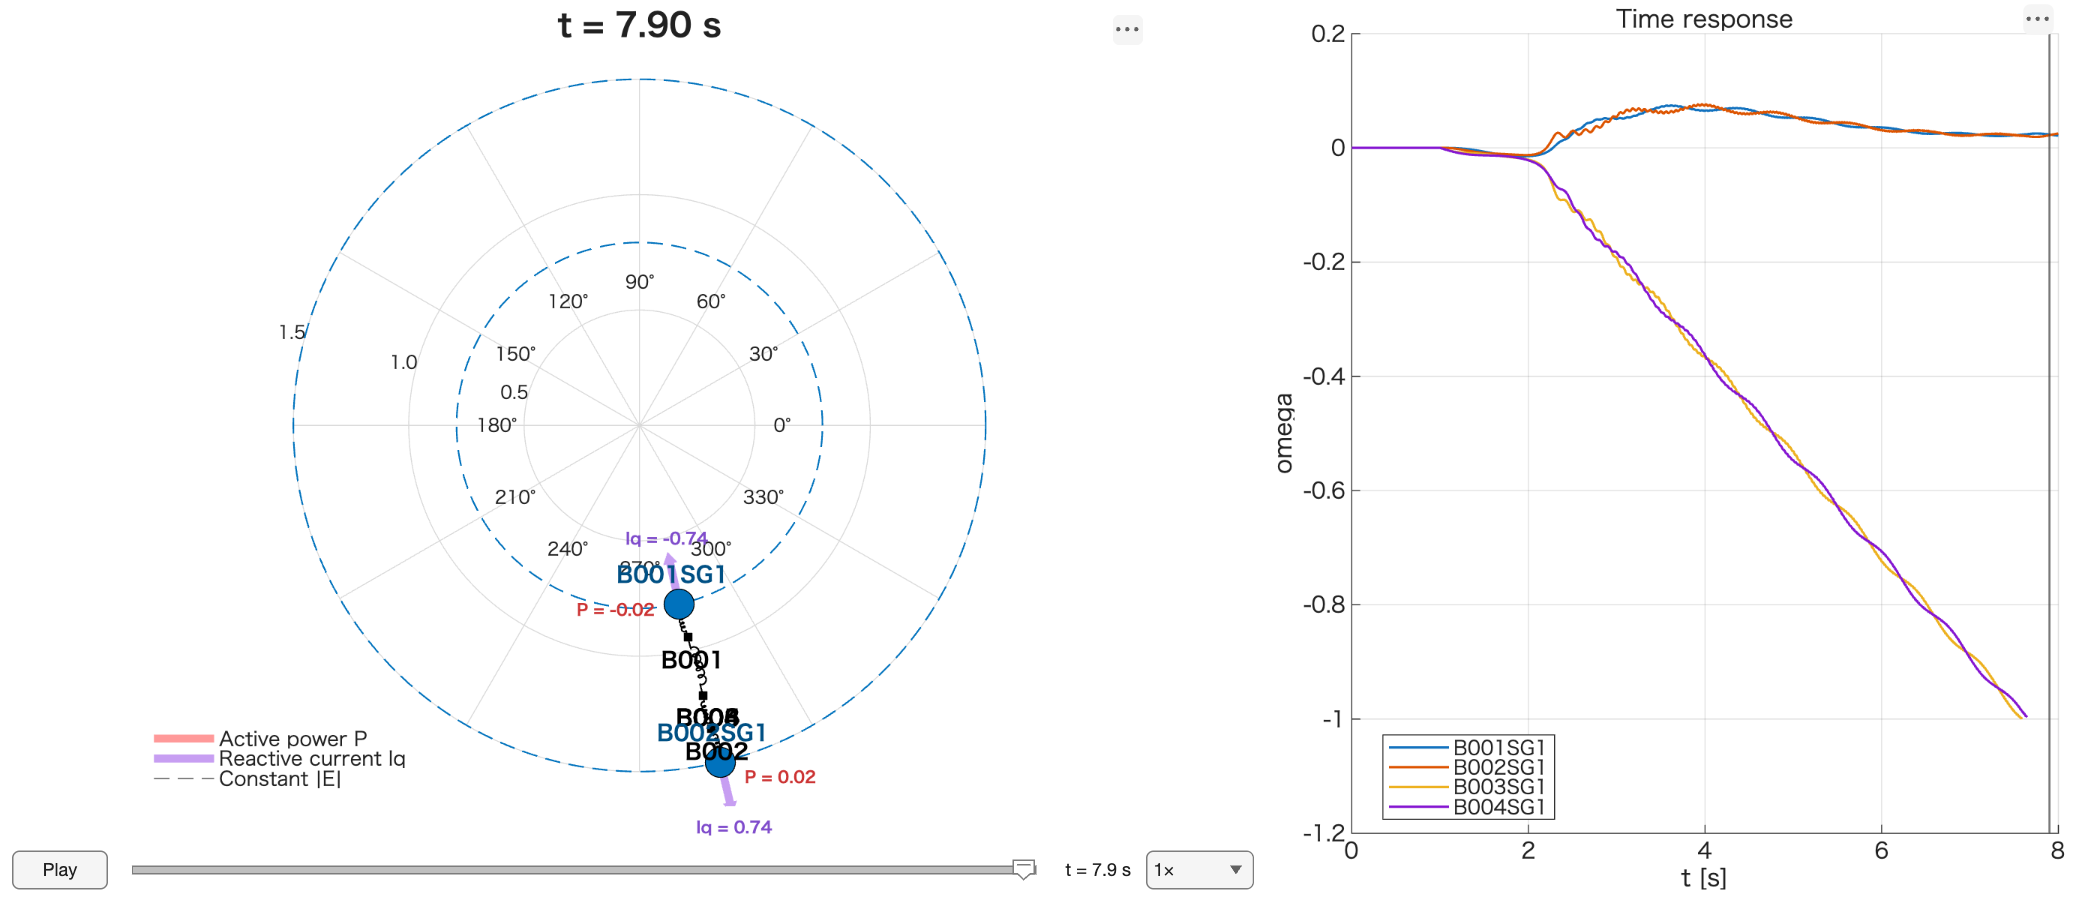

for i = 1:2
    sc.add_trip(sv_motor(i), rv_tStop(i));
end
result = net.simulate("step", Time=[0, 8], Progress="none", StopOnOutOfStep=false, MaxStep=0.005, SampleTime=0.01);
[G, G_chart] = result.plot_spring_model();
G.set_time(7.9);

電動機と発電機の間の角度がばねの支えられる範囲を超えて開き、t ≈ 2.2 s に回転子の角度の差が 180° を超えます。G3 と G4 は円を回って滑ります（脱調）。2 台は減速を続け、約 7.6 s に omega が −1 pu（−50 Hz）、つまり停止に達します。切り離された電動機は、その点もばねも矢印も、内部電圧の大きさを示す破線の円も、絵から消えます。負荷を失った G1 と G2 は速くなり、omega は t ≈ 3.6 s に約 0.07 pu まで上がったあと、ガバナの垂下特性で決まる、定格より高い値へ向かって下がっていきます（8 s で約 0.02 pu、1 Hz）。

**注意**: 図の動きは `G.animate()` で再生でき、`G.export_video("swing.mp4")` で動画（MPEG-4）に保存できます。ライブスクリプトの出力には動きが残らないので、ここでは時刻を選んで表示しています。

## 6. 3D で見る電圧崩壊：漏斗を滑り落ちる

定電力負荷は自分の点を持たず、3 節の力 $f_i$ で、つながる母線に働くだけです。円に沿って後ろへ向かうトルク $P$ と、消費する無効電力 $Q$ による、中心へ向かう力 $Q/|V|$ です。後者には危うい性質があります。負荷は電圧がいくらでも同じ $Q$ を求めるので、電圧が低いほど、点を中心へ引き込む力が強くなるのです。電圧が下がると引く力が強まり、電圧がさらに下がります。この繰り返しが電圧崩壊の引き金です。

平らな平面の上では、この様子は見えにくいままです。そこで平面に形を与え、各点を次の高さに持ち上げます。


$$z = \log|V|, \qquad \frac{\mathrm{d}z}{\mathrm{d}|V|} = \frac{1}{|V|}$$


点は漏斗の上を動くことになります。$|V|$ が 1 前後の縁ではほとんど平らで、底に向かうほど急になる曲面です（$\log$ は自然対数で、$|V| = 1$ で $z = 0$）。無効電力 $Q$ は、位置エネルギー $U = Q\,z = Q\log|V|$ を持つ一定の重さとして働かせます。このエネルギーが平面の上に生む力はその傾きで、


$$-\frac{\mathrm{d}U}{\mathrm{d}|V|} = -\frac{Q}{|V|}$$


となり、ちょうど負荷が中心へ引く力と一致します。漏斗が急なところほど、同じ重さでも内向きの力は強くなります（電圧が半分なら 2 倍）。

同梱の系統 `network.Tutorial6bus` の G4 を、母線 4 の定電力負荷 L4（`load-power`、P = −0.8、Q = −0.2 pu）に置き換え、G1 と G2 には 4 節と同じガバナと積分を付けます。t = 1 s から、G3 と L4 の消費をだんだん増やします（19 s でそれぞれ 0.3 pu 増える傾き）。add_input に時刻と値の表を渡すと、その間を直線で結んだ時系列になります。表の時刻は、入力を加える区間の始め（ここでは t = 1 s）から数えます。

net = network.Tutorial6bus();
net.a_Bus{4}.remove_component("B004SG1");
load4 = net.a_Bus{4}.add_component("load-power", P=-0.8, Q=-0.2);
for i = 1:2
    gen = net.a_Bus{i}.a_Component{1};
    gen.set_governor("gov-LPT3", parameter=sct_gov);
    net.add_global_controller("agc-PI", {gen}, parameter=struct(kP=0, kI=4));
end

INFO: The global controller 'PowerNetworkAGC1' is connected: Pmech_B001SG1_PowerNetworkAGC1 -> Pmech_B001SG1.
INFO: The global controller 'PowerNetworkAGC2' is connected: Pmech_B002SG1_PowerNetworkAGC2 -> Pmech_B002SG1.


net.initialize();
rm_ramp = [0, 0; 19, -0.3];          % [t = 1 s からの時間 (s), 増やす量 (pu)]
sc = net.add_scenario("ramp", Time=[0, 20]);
sc.add_input("B003SG1", "Pmech", rm_ramp, [1, 20]);
sc.add_input(load4.s_tag, "Pload", rm_ramp, [1, 20]);
[result, flag] = net.simulate("ramp", Progress="none", SampleTime=0.01);

flag

flag = -1

tab_V = result.get_trajectory("Vabs");
tab_V(end, :)

ans = 1×7 table
      t        B001       B002      B003      B004      B005      B006  
    ______    _______    ______    ______    _______    _____    _______

    7.2864    0.84901    1.2359    1.2036    0.73838    0.997    0.93589


flag が −1 で、シミュレーションは終わりの時刻の前、t ≈ 7.29 s に止まりました（上の警告）。このとき消費は 0.099 pu 増え、母線 4 の |V| は約 0.74 pu です。ここで、ばねのつり合いがなくなります。L4 が定電力負荷のままでは、この先の方程式に解がなく、`net.simulate` はそこで止まります。

### その先を見る：インピーダンス負荷で続ける

その先を見るため、L4 をインピーダンス負荷（`load-impedance`）にして、2 回目のシミュレーションをします。抵抗とリアクタンスは add_input の時系列で与えます。t = 7.26 s（止まる 3 サンプル前）までは、1 回目で L4 が電力を受け取っていたときのインピーダンス（アドミタンス $Y = -\overline{S}/|V|^2$）、その後はアドミタンスが同じ割合で増え続けるようにします。負荷がさらに電力を引き込もうとし続ける、という想定です。母線 4 の |V| が 0.07 pu になる t = 9.48 s まで計算します。

tab_P = result.get_trajectory("Pload");
tab_Q = result.get_trajectory("Qload");
[rv_t, iv_u] = unique(tab_P.t);                 % 事象の時刻は 2 回現れる
rv_Y = -(tab_P{iv_u, 2} - 1j*tab_Q{iv_u, 2}) ./ tab_V.B004(iv_u).^2;   % L4 のアドミタンス
k_end = numel(rv_t) - 3;                         % 止まる 3 サンプル前 (t = 7.26 s)
r_rate = log(abs(rv_Y(k_end)) / abs(rv_Y(k_end - 3))) / (rv_t(k_end) - rv_t(k_end - 3));   % 増える割合 [1/s]
rv_tIn = (0:0.01:19)';                           % 入力の時刻 [t = 1 s からの時間 (s)]
rv_YIn = interp1(rv_t(1:k_end), rv_Y(1:k_end), 1 + rv_tIn);
iv_next = 1 + rv_tIn > rv_t(k_end);
rv_YIn(iv_next) = rv_Y(k_end) * exp(r_rate*(1 + rv_tIn(iv_next) - rv_t(k_end)));
rv_dZ = 1 ./ rv_YIn - 1 / rv_Y(1);               % 平衡点のインピーダンスに足す量

net.a_Bus{4}.remove_component(load4.s_tag);
load4 = net.a_Bus{4}.add_component("load-impedance", P=-0.8, Q=-0.2);
net.initialize();
sc = net.add_scenario("impedance", Time=[0, 20]);
sc.add_input("B003SG1", "Pmech", rm_ramp, [1, 20]);
sc.add_input(load4.s_tag, ["R"; "X"], [rv_tIn, real(rv_dZ), imag(rv_dZ)], [1, 20]);
resultZ = net.simulate("impedance", Time=[0, 9.48], Progress="none", SampleTime=0.01);

同じ結果を、フェーザの平面（`Dimension=2`）と漏斗 z = log|V| の上（`Dimension=3`）に描き、すべての母線の |V| と、母線 4 に注入される有効電力 P のグラフ（`plot_trajectory`）と `link` でつなぎます。どれか 1 つで時刻を動かすと、ほかも同じ時刻へ動きます。ここでは t = 8.5 s を表示します。

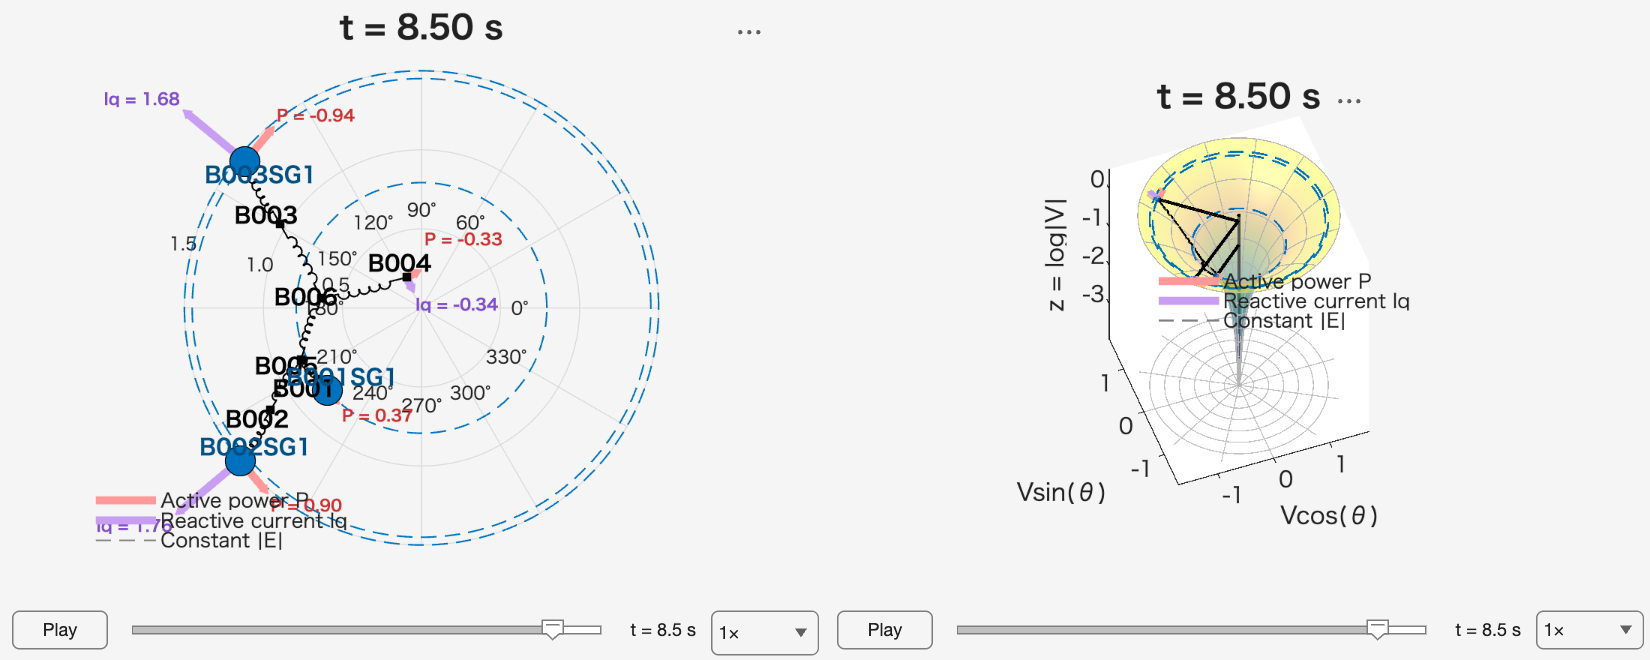

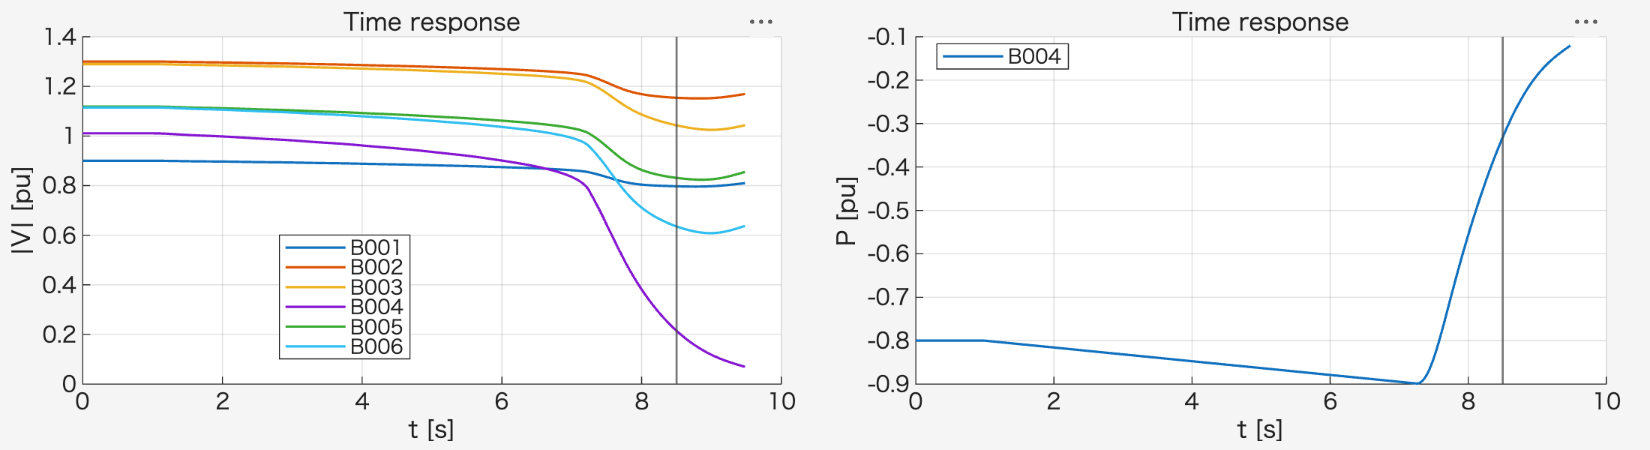

fig = figure(Position=[100 100 1100 440]);
G = resultZ.plot_spring_model(Dimension=2, Trajectory="none", Parent=uipanel(fig, Position=[0 0 0.5 1], BorderType="none"));
G3 = resultZ.plot_spring_model(Dimension=3, Trajectory="none", Parent=uipanel(fig, Position=[0.5 0 0.5 1], BorderType="none"));
figChart = figure(Position=[100 100 1100 300]);
G_V = resultZ.plot_trajectory(Quantity="Vabs", Parent=uipanel(figChart, Position=[0 0 0.5 1], BorderType="none"));
G_P = resultZ.plot_trajectory(Quantity="P", Bus="B004", Parent=uipanel(figChart, Position=[0.5 0 0.5 1], BorderType="none"));
G.link(G3);
G.link(G_V);
G.link(G_P);
G.set_time(8.5);

母線 4 が内側へ、漏斗の斜面の下へ動き、L4 の紫の矢印（内向きの力 Q/|V|）は電圧が下がるにつれて大きくなります。2 回目のシミュレーションでは、母線 4 は漏斗を落ちていき、|V| は 7.75 s で約 0.5 pu、9.48 s で 0.07 pu になります。L4 が実際に受け取る電力は約 0.9 pu から 0.1 pu へ向かって減り（下の右のグラフ。母線 4 に注入される P は、L4 が受け取る電力に負の符号を付けたものです）、G1〜G3 は速くなります。電圧崩壊は「方程式の解がなくなる」というだけのことではなく、漏斗の上の質点をばねが支えきれなくなることとして見ることができます。

漏斗は、2 種類の電力のつながりも見せてくれます。平面の向きでは、有効電力が点を中心のまわりに回します（$P$ と $\delta$ の関係）。高さの向きでは、無効電力が点を上下させます（$Q$ と $V$ の関係）。点は曲がった面の上に縛られているので、一方の向きの動きが、もう一方の向きの力を変えます。

**注意**

- 3D の図の `G.RMin` と `G.RMax` は描く曲面の範囲 [pu]、`G.View` はカメラの向き（方位角と仰角）、`G.SurfaceAlpha` は曲面の不透明度です。図の上でマウスで回すこともできます。

- `G.animate()` を呼ぶと、図が動き出します（`G.animate(Speed=0.5)` で半分の速さ）。つないだ図もいっしょに動きます。知識ページのアニメーションは、この節の図を時刻を進めながら動画にしたものです（名前や色などの見た目は変えています）。

- 定インピーダンス負荷では、電圧が下がると無効電力も減るので、このような崩壊は起こりにくくなります。この節で L4 を定電力負荷にしたのはそのためです。2 回目のシミュレーションでは、インピーダンスを時系列で変えて、負荷が電力を引き込もうとし続ける様子を作っています。

## 7. GUILDA でばね質点モデルを描く

この Part の図は、すべて `plot_spring_model` という名前のメソッドで描きました。どれも、母線を点、発電機の内部電圧をその発電機自身の点、ブランチと発電機のリアクタンスをばねとして描き、有効電力 $P$ と無効電流 $I_q$ の矢印を添えます。

- **平衡点**（`net.plot_spring_model`）: `net.initialize()` の後の平衡点を 1 枚の絵に描きます（3 節）。

- **潮流計算の結果**（`pf.plot_spring_model`）: 母線だけを描きます。潮流計算は発電機の状態を求めないからです（3 節）。

- **シミュレーションの結果**（`res.plot_spring_model`）: 出力したすべての時刻を持ちます。`set_time` で時刻を選び、`animate` で再生し、`export_video` で動画に保存します（4〜6 節）。

- **2D と 3D**（`Dimension=2`、`Dimension=3`）: フェーザの平面、または漏斗 $z = \log|V|$ の上に描きます（6 節）。

シミュレーションの結果の `[G, G_chart] = result.plot_spring_model()` は、1 つの図の左に絵 `G`、右に横のグラフ `G_chart`（既定では発電機の omega。オプション `Trajectory` で `plot_trajectory` のほかの量を選び、`Trajectory="none"` で絵だけを描きます）を並べます。2 つはつながっていて、`G.set_time`、`G.animate`、再生バーで時刻を動かすと、`G_chart` の縦線も同じ時刻へ動きます。`G.link(G2)` で、ほかの図もつなげます（6 節）。よく使う設定は次のとおりです。

- `G.ShowValue`（矢印の値）、`G.ShowLabel`（点の名前）、`G.ShowLegend`（凡例）で表示を切り替え、`G.ArrowScaleP` と `G.ArrowScaleQ` で矢印の長さを変えます。

- `G.set_style(タグ, Color=..., MarkerSize=...)` で、点やばねの見た目を 1 つずつ変えます。タグは母線（`B004` など）、発電機（`B002SG1` など）、ブランチのタグです。横のグラフの線も `G_chart.set_style(タグ, Color=...)` で変えられます。

- `G.RotationScale = 0` で母線に共通の回転を除いて描きます（既定の 1 は実際の回転）。

- `G.ax` が図の軸で、`axis(G.ax, ...)` のように MATLAB の普通の軸の操作ができます。

GUILDA の発電機のモデル（古典・1 軸・2 軸・Park・ドループ）は、どれも内部電圧を自分の点として持ちます。負荷は自分の点を持たず、その働きは母線の矢印として現れます。

## まとめ

- 定格の周波数で回る座標から見ると、各母線の電圧は平面上の点 $V_i = |V_i|e^{j\theta_i}$ になります。周波数の変化は、すべての点の共通の回転として見えます。

- 送電線は、ばね係数 $B = 1/X$ のばねで、その力は線路電流の $-j$ 倍です。円に沿う向きのトルクが有効電力、中心へ向かう力が無効電流 $Q/|V|$ に対応することを、潮流計算の結果で確かめました。

- 潮流計算の解は、すべてのばねがつり合う位置です。負荷を増やすと、ばねが伸びて角度の差が開きます。

- 負荷が増えると絵全体が後ろへ回り（周波数の低下）、発電機の質量（慣性）がその動き出しをゆるやかにします。ガバナは回転を遅くし、ずれの積分（AGC の役目）は周波数を定格の値へ戻します。

- ばねが引き戻すトルクは 90° で最大です。ばねが支えきれないところまで押し出された点は、円を回って滑ります。これが脱調です。

- 漏斗 $z = \log|V|$ の上では、無効電力は位置エネルギー $Q\log|V|$ を持つ一定の重さになり、電圧崩壊は点が漏斗の底へ滑り落ちる運動として見えます。

- シミュレーションの結果は `[G, G_chart] = result.plot_spring_model()` で、ばね質点の絵 `G` と、発電機の omega の横のグラフ `G_chart` を並べて描きます。`G.set_time` で時刻を選び、`G.animate()` で動かします。2D と 3D の絵やほかのグラフは `link` でつなげます。

## 次の Part

Part 5「近似線形化」では、平衡点のまわりの小さな揺れを線形モデルで表し、固有値から揺れの型を読み取ります。知識ページ: [Part 5: 近似線形化](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part5-linearization.html","-browser"))

[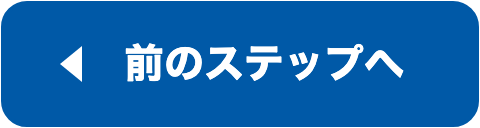](matlab:open('Part3_TimeSimulation.mlx'))　　[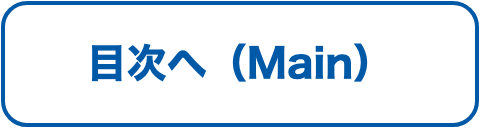](matlab:open('Main.mlx'))　　[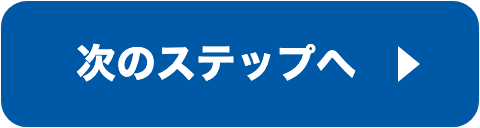](matlab:open('Part5_Linearization.mlx'))